# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       computeCostMulti.m      ex1data1.txt            gradientDescent.m       normalEqn.m             token.mat               
..                      ex1.mlx                 ex1data2.txt            gradientDescentMulti.m  plotData.m              warmUpExercise.m        
computeCost.m           ex1_companion.mlx       featureNormalize.m      lib                     submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

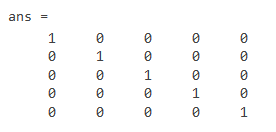

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

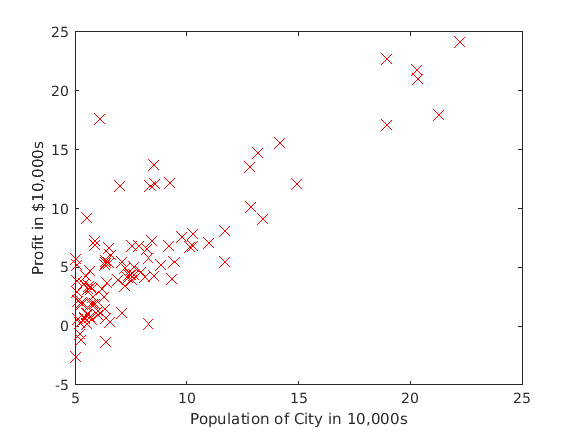

 plotData(X, y);

The resulting plot should appear as in Figure 1 below:

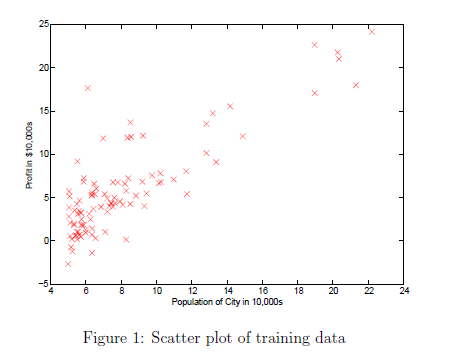

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\mathrm{simultaneously}\;\mathrm{update}\;\theta_{j\;} \;\mathrm{for}\;\mathrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term (${\theta \prime \ldotp }_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

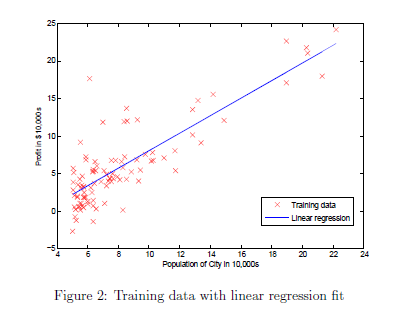    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

theta =     0.0584
    0.6533


J = 6.7372

theta =     0.0629
    0.7700


J = 5.9316

theta =     0.0578
    0.7913


J = 5.9012

theta =     0.0511
    0.7957


J = 5.8952

theta =     0.0440
    0.7971


J = 5.8901

theta =     0.0369
    0.7979


J = 5.8850

theta =     0.0298
    0.7987


J = 5.8799

theta =     0.0228
    0.7994


J = 5.8749

theta =     0.0157
    0.8001


J = 5.8698

theta =     0.0086
    0.8008


J = 5.8648

theta =     0.0016
    0.8015


J = 5.8598

theta =    -0.0054
    0.8022


J = 5.8548

theta =    -0.0124
    0.8029


J = 5.8499

theta =    -0.0194
    0.8036


J = 5.8449

theta =    -0.0264
    0.8043


J = 5.8400

theta =    -0.0334
    0.8050


J = 5.8351

theta =    -0.0404
    0.8057


J = 5.8302

theta =    -0.0473
    0.8064


J = 5.8253

theta =    -0.0542
    0.8071


J = 5.8205

theta =    -0.0612
    0.8078


J = 5.8156

theta =    -0.0681
    0.8085


J = 5.8108

theta =    -0.0750
    0.8092


J = 5.8060

theta =    -0.0819
    0.8099


J = 5.8012

theta =    -0.0887
    0.8106


J = 5.7965

theta =    -0.0956
    0.8113


J = 5.7917

theta =    -0.1025
    0.8120


J = 5.7870

theta =    -0.1093
    0.8126


J = 5.7822

theta =    -0.1161
    0.8133


J = 5.7775

theta =    -0.1229
    0.8140


J = 5.7729

theta =    -0.1297
    0.8147


J = 5.7682

theta =    -0.1365
    0.8154


J = 5.7635

theta =    -0.1433
    0.8161


J = 5.7589

theta =    -0.1501
    0.8167


J = 5.7543

theta =    -0.1568
    0.8174


J = 5.7497

theta =    -0.1636
    0.8181


J = 5.7451

theta =    -0.1703
    0.8188


J = 5.7405

theta =    -0.1770
    0.8194


J = 5.7360

theta =    -0.1837
    0.8201


J = 5.7315

theta =    -0.1904
    0.8208


J = 5.7269

theta =    -0.1971
    0.8215


J = 5.7224

theta =    -0.2037
    0.8221


J = 5.7179

theta =    -0.2104
    0.8228


J = 5.7135

theta =    -0.2170
    0.8235


J = 5.7090

theta =    -0.2237
    0.8241


J = 5.7046

theta =    -0.2303
    0.8248


J = 5.7002

theta =    -0.2369
    0.8255


J = 5.6958

theta =    -0.2435
    0.8261


J = 5.6914

theta =    -0.2501
    0.8268


J = 5.6870

theta =    -0.2566
    0.8274


J = 5.6826

theta = 2×1
   -0.2632
    0.8281


J = 5.6783

theta = 2×1
   -0.2698
    0.8288


J = 5.6740

theta = 2×1
   -0.2763
    0.8294


J = 5.6697

theta = 2×1
   -0.2828
    0.8301


J = 5.6654

theta = 2×1
   -0.2893
    0.8307


J = 5.6611

theta = 2×1
   -0.2958
    0.8314


J = 5.6568

theta = 2×1
   -0.3023
    0.8320


J = 5.6526

theta = 2×1
   -0.3088
    0.8327


J = 5.6483

theta = 2×1
   -0.3153
    0.8333


J = 5.6441

theta = 2×1
   -0.3217
    0.8340


J = 5.6399

theta = 2×1
   -0.3282
    0.8346


J = 5.6357

theta = 2×1
   -0.3346
    0.8353


J = 5.6315

theta = 2×1
   -0.3410
    0.8359


J = 5.6274

theta = 2×1
   -0.3474
    0.8366


J = 5.6232

theta = 2×1
   -0.3538
    0.8372


J = 5.6191

theta = 2×1
   -0.3602
    0.8378


J = 5.6150

theta = 2×1
   -0.3666
    0.8385


J = 5.6109

theta = 2×1
   -0.3729
    0.8391


J = 5.6068

theta = 2×1
   -0.3793
    0.8398


J = 5.6027

theta = 2×1
   -0.3856
    0.8404


J = 5.5987

theta = 2×1
   -0.3919
    0.8410


J = 5.5946

theta = 2×1
   -0.3983
    0.8417


J = 5.5906

theta = 2×1
   -0.4046
    0.8423


J = 5.5866

theta = 2×1
   -0.4109
    0.8429


J = 5.5826

theta = 2×1
   -0.4171
    0.8436


J = 5.5786

theta = 2×1
   -0.4234
    0.8442


J = 5.5747

theta = 2×1
   -0.4297
    0.8448


J = 5.5707

theta = 2×1
   -0.4359
    0.8455


J = 5.5668

theta = 2×1
   -0.4422
    0.8461


J = 5.5628

theta = 2×1
   -0.4484
    0.8467


J = 5.5589

theta = 2×1
   -0.4546
    0.8473


J = 5.5550

theta = 2×1
   -0.4608
    0.8480


J = 5.5512

theta = 2×1
   -0.4670
    0.8486


J = 5.5473

theta = 2×1
   -0.4732
    0.8492


J = 5.5434

theta = 2×1
   -0.4793
    0.8498


J = 5.5396

theta = 2×1
   -0.4855
    0.8504


J = 5.5358

theta = 2×1
   -0.4916
    0.8511


J = 5.5319

theta = 2×1
   -0.4978
    0.8517


J = 5.5281

theta = 2×1
   -0.5039
    0.8523


J = 5.5244

theta = 2×1
   -0.5100
    0.8529


J = 5.5206

theta = 2×1
   -0.5161
    0.8535


J = 5.5168

theta = 2×1
   -0.5222
    0.8541


J = 5.5131

theta = 2×1
   -0.5283
    0.8547


J = 5.5094

theta = 2×1
   -0.5344
    0.8553


J = 5.5056

theta = 2×1
   -0.5404
    0.8560


J = 5.5019

theta = 2×1
   -0.5465
    0.8566


J = 5.4982

theta = 2×1
   -0.5525
    0.8572


J = 5.4946

theta = 2×1
   -0.5585
    0.8578


J = 5.4909

theta = 2×1
   -0.5646
    0.8584


J = 5.4872

theta = 2×1
   -0.5706
    0.8590


J = 5.4836

theta = 2×1
   -0.5766
    0.8596


J = 5.4800

theta = 2×1
   -0.5825
    0.8602


J = 5.4764

theta = 2×1
   -0.5885
    0.8608


J = 5.4728

theta = 2×1
   -0.5945
    0.8614


J = 5.4692

theta = 2×1
   -0.6004
    0.8620


J = 5.4656

theta = 2×1
   -0.6064
    0.8626


J = 5.4620

theta = 2×1
   -0.6123
    0.8632


J = 5.4585

theta = 2×1
   -0.6182
    0.8638


J = 5.4550

theta = 2×1
   -0.6241
    0.8644


J = 5.4514

theta = 2×1
   -0.6300
    0.8650


J = 5.4479

theta = 2×1
   -0.6359
    0.8655


J = 5.4444

theta = 2×1
   -0.6418
    0.8661


J = 5.4409

theta = 2×1
   -0.6476
    0.8667


J = 5.4375

theta = 2×1
   -0.6535
    0.8673


J = 5.4340

theta = 2×1
   -0.6593
    0.8679


J = 5.4306

theta = 2×1
   -0.6652
    0.8685


J = 5.4271

theta = 2×1
   -0.6710
    0.8691


J = 5.4237

theta = 2×1
   -0.6768
    0.8697


J = 5.4203

theta = 2×1
   -0.6826
    0.8702


J = 5.4169

theta = 2×1
   -0.6884
    0.8708


J = 5.4135

theta = 2×1
   -0.6942
    0.8714


J = 5.4101

theta = 2×1
   -0.7000
    0.8720


J = 5.4068

theta = 2×1
   -0.7057
    0.8726


J = 5.4034

theta = 2×1
   -0.7115
    0.8731


J = 5.4001

theta = 2×1
   -0.7172
    0.8737


J = 5.3968

theta = 2×1
   -0.7229
    0.8743


J = 5.3935

theta = 2×1
   -0.7287
    0.8749


J = 5.3902

theta = 2×1
   -0.7344
    0.8754


J = 5.3869

theta = 2×1
   -0.7401
    0.8760


J = 5.3836

theta = 2×1
   -0.7458
    0.8766


J = 5.3803

theta = 2×1
   -0.7514
    0.8772


J = 5.3771

theta = 2×1
   -0.7571
    0.8777


J = 5.3738

theta = 2×1
   -0.7628
    0.8783


J = 5.3706

theta = 2×1
   -0.7684
    0.8789


J = 5.3674

theta = 2×1
   -0.7740
    0.8794


J = 5.3642

theta = 2×1
   -0.7797
    0.8800


J = 5.3610

theta = 2×1
   -0.7853
    0.8806


J = 5.3578

theta = 2×1
   -0.7909
    0.8811


J = 5.3546

theta = 2×1
   -0.7965
    0.8817


J = 5.3515

theta = 2×1
   -0.8021
    0.8822


J = 5.3483

theta = 2×1
   -0.8077
    0.8828


J = 5.3452

theta = 2×1
   -0.8132
    0.8834


J = 5.3420

theta = 2×1
   -0.8188
    0.8839


J = 5.3389

theta = 2×1
   -0.8243
    0.8845


J = 5.3358

theta = 2×1
   -0.8299
    0.8850


J = 5.3327

theta = 2×1
   -0.8354
    0.8856


J = 5.3296

theta = 2×1
   -0.8409
    0.8861


J = 5.3266

theta = 2×1
   -0.8464
    0.8867


J = 5.3235

theta = 2×1
   -0.8519
    0.8872


J = 5.3205

theta = 2×1
   -0.8574
    0.8878


J = 5.3174

theta = 2×1
   -0.8629
    0.8883


J = 5.3144

theta = 2×1
   -0.8683
    0.8889


J = 5.3114

theta = 2×1
   -0.8738
    0.8894


J = 5.3084

theta = 2×1
   -0.8793
    0.8900


J = 5.3054

theta = 2×1
   -0.8847
    0.8905


J = 5.3024

theta = 2×1
   -0.8901
    0.8911


J = 5.2994

theta = 2×1
   -0.8955
    0.8916


J = 5.2965

theta = 2×1
   -0.9009
    0.8922


J = 5.2935

theta = 2×1
   -0.9063
    0.8927


J = 5.2906

theta = 2×1
   -0.9117
    0.8933


J = 5.2876

theta = 2×1
   -0.9171
    0.8938


J = 5.2847

theta = 2×1
   -0.9225
    0.8943


J = 5.2818

theta = 2×1
   -0.9278
    0.8949


J = 5.2789

theta = 2×1
   -0.9332
    0.8954


J = 5.2760

theta = 2×1
   -0.9385
    0.8959


J = 5.2731

theta = 2×1
   -0.9439
    0.8965


J = 5.2703

theta = 2×1
   -0.9492
    0.8970


J = 5.2674

theta = 2×1
   -0.9545
    0.8975


J = 5.2646

theta = 2×1
   -0.9598
    0.8981


J = 5.2617

theta = 2×1
   -0.9651
    0.8986


J = 5.2589

theta = 2×1
   -0.9704
    0.8991


J = 5.2561

theta = 2×1
   -0.9756
    0.8997


J = 5.2533

theta = 2×1
   -0.9809
    0.9002


J = 5.2505

theta = 2×1
   -0.9862
    0.9007


J = 5.2477

theta = 2×1
   -0.9914
    0.9013


J = 5.2449

theta = 2×1
   -0.9966
    0.9018


J = 5.2422

theta = 2×1
   -1.0019
    0.9023


J = 5.2394

theta = 2×1
   -1.0071
    0.9028


J = 5.2367

theta = 2×1
   -1.0123
    0.9034


J = 5.2339

theta = 2×1
   -1.0175
    0.9039


J = 5.2312

theta = 2×1
   -1.0227
    0.9044


J = 5.2285

theta = 2×1
   -1.0279
    0.9049


J = 5.2258

theta = 2×1
   -1.0330
    0.9054


J = 5.2231

theta = 2×1
   -1.0382
    0.9060


J = 5.2204

theta = 2×1
   -1.0433
    0.9065


J = 5.2177

theta = 2×1
   -1.0485
    0.9070


J = 5.2150

theta = 2×1
   -1.0536
    0.9075


J = 5.2124

theta = 2×1
   -1.0587
    0.9080


J = 5.2097

theta = 2×1
   -1.0638
    0.9085


J = 5.2071

theta = 2×1
   -1.0690
    0.9090


J = 5.2045

theta = 2×1
   -1.0740
    0.9096


J = 5.2018

theta = 2×1
   -1.0791
    0.9101


J = 5.1992

theta = 2×1
   -1.0842
    0.9106


J = 5.1966

theta = 2×1
   -1.0893
    0.9111


J = 5.1940

theta = 2×1
   -1.0943
    0.9116


J = 5.1915

theta = 2×1
   -1.0994
    0.9121


J = 5.1889

theta = 2×1
   -1.1044
    0.9126


J = 5.1863

theta = 2×1
   -1.1095
    0.9131


J = 5.1838

theta = 2×1
   -1.1145
    0.9136


J = 5.1812

theta = 2×1
   -1.1195
    0.9141


J = 5.1787

theta = 2×1
   -1.1245
    0.9146


J = 5.1762

theta = 2×1
   -1.1295
    0.9151


J = 5.1736

theta = 2×1
   -1.1345
    0.9156


J = 5.1711

theta = 2×1
   -1.1395
    0.9161


J = 5.1686

theta = 2×1
   -1.1444
    0.9166


J = 5.1661

theta = 2×1
   -1.1494
    0.9171


J = 5.1637

theta = 2×1
   -1.1543
    0.9176


J = 5.1612

theta = 2×1
   -1.1593
    0.9181


J = 5.1587

theta = 2×1
   -1.1642
    0.9186


J = 5.1563

theta = 2×1
   -1.1691
    0.9191


J = 5.1538

theta = 2×1
   -1.1741
    0.9196


J = 5.1514

theta = 2×1
   -1.1790
    0.9201


J = 5.1489

theta = 2×1
   -1.1839
    0.9206


J = 5.1465

theta = 2×1
   -1.1887
    0.9211


J = 5.1441

theta = 2×1
   -1.1936
    0.9216


J = 5.1417

theta = 2×1
   -1.1985
    0.9221


J = 5.1393

theta = 2×1
   -1.2034
    0.9226


J = 5.1369

theta = 2×1
   -1.2082
    0.9230


J = 5.1346

theta = 2×1
   -1.2131
    0.9235


J = 5.1322

theta = 2×1
   -1.2179
    0.9240


J = 5.1298

theta = 2×1
   -1.2227
    0.9245


J = 5.1275

theta = 2×1
   -1.2275
    0.9250


J = 5.1251

theta = 2×1
   -1.2323
    0.9255


J = 5.1228

theta = 2×1
   -1.2371
    0.9259


J = 5.1205

theta = 2×1
   -1.2419
    0.9264


J = 5.1181

theta = 2×1
   -1.2467
    0.9269


J = 5.1158

theta = 2×1
   -1.2515
    0.9274


J = 5.1135

theta = 2×1
   -1.2563
    0.9279


J = 5.1112

theta = 2×1
   -1.2610
    0.9283


J = 5.1090

theta = 2×1
   -1.2658
    0.9288


J = 5.1067

theta = 2×1
   -1.2705
    0.9293


J = 5.1044

theta = 2×1
   -1.2752
    0.9298


J = 5.1022

theta = 2×1
   -1.2800
    0.9302


J = 5.0999

theta = 2×1
   -1.2847
    0.9307


J = 5.0977

theta = 2×1
   -1.2894
    0.9312


J = 5.0954

theta = 2×1
   -1.2941
    0.9317


J = 5.0932

theta = 2×1
   -1.2988
    0.9321


J = 5.0910

theta = 2×1
   -1.3035
    0.9326


J = 5.0888

theta = 2×1
   -1.3081
    0.9331


J = 5.0866

theta = 2×1
   -1.3128
    0.9335


J = 5.0844

theta = 2×1
   -1.3175
    0.9340


J = 5.0822

theta = 2×1
   -1.3221
    0.9345


J = 5.0800

theta = 2×1
   -1.3267
    0.9349


J = 5.0778

theta = 2×1
   -1.3314
    0.9354


J = 5.0757

theta = 2×1
   -1.3360
    0.9359


J = 5.0735

theta = 2×1
   -1.3406
    0.9363


J = 5.0714

theta = 2×1
   -1.3452
    0.9368


J = 5.0692

theta = 2×1
   -1.3498
    0.9373


J = 5.0671

theta = 2×1
   -1.3544
    0.9377


J = 5.0650

theta = 2×1
   -1.3590
    0.9382


J = 5.0628

theta = 2×1
   -1.3636
    0.9386


J = 5.0607

theta = 2×1
   -1.3681
    0.9391


J = 5.0586

theta = 2×1
   -1.3727
    0.9396


J = 5.0565

theta = 2×1
   -1.3772
    0.9400


J = 5.0544

theta = 2×1
   -1.3818
    0.9405


J = 5.0524

theta = 2×1
   -1.3863
    0.9409


J = 5.0503

theta = 2×1
   -1.3908
    0.9414


J = 5.0482

theta = 2×1
   -1.3953
    0.9418


J = 5.0462

theta = 2×1
   -1.3998
    0.9423


J = 5.0441

theta = 2×1
   -1.4043
    0.9427


J = 5.0421

theta = 2×1
   -1.4088
    0.9432


J = 5.0400

theta = 2×1
   -1.4133
    0.9436


J = 5.0380

theta = 2×1
   -1.4178
    0.9441


J = 5.0360

theta = 2×1
   -1.4223
    0.9445


J = 5.0340

theta = 2×1
   -1.4267
    0.9450


J = 5.0320

theta = 2×1
   -1.4312
    0.9454


J = 5.0300

theta = 2×1
   -1.4356
    0.9459


J = 5.0280

theta = 2×1
   -1.4400
    0.9463


J = 5.0260

theta = 2×1
   -1.4445
    0.9468


J = 5.0240

theta = 2×1
   -1.4489
    0.9472


J = 5.0220

theta = 2×1
   -1.4533
    0.9477


J = 5.0201

theta = 2×1
   -1.4577
    0.9481


J = 5.0181

theta = 2×1
   -1.4621
    0.9485


J = 5.0162

theta = 2×1
   -1.4665
    0.9490


J = 5.0142

theta = 2×1
   -1.4709
    0.9494


J = 5.0123

theta = 2×1
   -1.4752
    0.9499


J = 5.0104

theta = 2×1
   -1.4796
    0.9503


J = 5.0085

theta = 2×1
   -1.4840
    0.9507


J = 5.0065

theta = 2×1
   -1.4883
    0.9512


J = 5.0046

theta = 2×1
   -1.4926
    0.9516


J = 5.0027

theta = 2×1
   -1.4970
    0.9520


J = 5.0008

theta = 2×1
   -1.5013
    0.9525


J = 4.9989

theta = 2×1
   -1.5056
    0.9529


J = 4.9971

theta = 2×1
   -1.5099
    0.9533


J = 4.9952

theta = 2×1
   -1.5142
    0.9538


J = 4.9933

theta = 2×1
   -1.5185
    0.9542


J = 4.9915

theta = 2×1
   -1.5228
    0.9546


J = 4.9896

theta = 2×1
   -1.5271
    0.9551


J = 4.9878

theta = 2×1
   -1.5313
    0.9555


J = 4.9859

theta = 2×1
   -1.5356
    0.9559


J = 4.9841

theta = 2×1
   -1.5399
    0.9564


J = 4.9823

theta = 2×1
   -1.5441
    0.9568


J = 4.9805

theta = 2×1
   -1.5484
    0.9572


J = 4.9786

theta = 2×1
   -1.5526
    0.9576


J = 4.9768

theta = 2×1
   -1.5568
    0.9581


J = 4.9750

theta = 2×1
   -1.5610
    0.9585


J = 4.9732

theta = 2×1
   -1.5652
    0.9589


J = 4.9714

theta = 2×1
   -1.5694
    0.9593


J = 4.9697

theta = 2×1
   -1.5736
    0.9597


J = 4.9679

theta = 2×1
   -1.5778
    0.9602


J = 4.9661

theta = 2×1
   -1.5820
    0.9606


J = 4.9644

theta = 2×1
   -1.5862
    0.9610


J = 4.9626

theta = 2×1
   -1.5903
    0.9614


J = 4.9609

theta = 2×1
   -1.5945
    0.9618


J = 4.9591

theta = 2×1
   -1.5986
    0.9623


J = 4.9574

theta = 2×1
   -1.6028
    0.9627


J = 4.9556

theta = 2×1
   -1.6069
    0.9631


J = 4.9539

theta = 2×1
   -1.6110
    0.9635


J = 4.9522

theta = 2×1
   -1.6151
    0.9639


J = 4.9505

theta = 2×1
   -1.6193
    0.9643


J = 4.9488

theta = 2×1
   -1.6234
    0.9647


J = 4.9471

theta = 2×1
   -1.6275
    0.9652


J = 4.9454

theta = 2×1
   -1.6315
    0.9656


J = 4.9437

theta = 2×1
   -1.6356
    0.9660


J = 4.9420

theta = 2×1
   -1.6397
    0.9664


J = 4.9404

theta = 2×1
   -1.6438
    0.9668


J = 4.9387

theta = 2×1
   -1.6478
    0.9672


J = 4.9370

theta = 2×1
   -1.6519
    0.9676


J = 4.9354

theta = 2×1
   -1.6559
    0.9680


J = 4.9337

theta = 2×1
   -1.6600
    0.9684


J = 4.9321

theta = 2×1
   -1.6640
    0.9688


J = 4.9304

theta = 2×1
   -1.6680
    0.9692


J = 4.9288

theta = 2×1
   -1.6720
    0.9696


J = 4.9272

theta = 2×1
   -1.6760
    0.9700


J = 4.9255

theta = 2×1
   -1.6800
    0.9704


J = 4.9239

theta = 2×1
   -1.6840
    0.9708


J = 4.9223

theta = 2×1
   -1.6880
    0.9712


J = 4.9207

theta = 2×1
   -1.6920
    0.9716


J = 4.9191

theta = 2×1
   -1.6960
    0.9720


J = 4.9175

theta = 2×1
   -1.6999
    0.9724


J = 4.9159

theta = 2×1
   -1.7039
    0.9728


J = 4.9144

theta = 2×1
   -1.7079
    0.9732


J = 4.9128

theta = 2×1
   -1.7118
    0.9736


J = 4.9112

theta = 2×1
   -1.7157
    0.9740


J = 4.9096

theta = 2×1
   -1.7197
    0.9744


J = 4.9081

theta = 2×1
   -1.7236
    0.9748


J = 4.9065

theta = 2×1
   -1.7275
    0.9752


J = 4.9050

theta = 2×1
   -1.7314
    0.9756


J = 4.9034

theta = 2×1
   -1.7353
    0.9760


J = 4.9019

theta = 2×1
   -1.7392
    0.9764


J = 4.9004

theta = 2×1
   -1.7431
    0.9768


J = 4.8989

theta = 2×1
   -1.7470
    0.9772


J = 4.8973

theta = 2×1
   -1.7508
    0.9776


J = 4.8958

theta = 2×1
   -1.7547
    0.9779


J = 4.8943

theta = 2×1
   -1.7586
    0.9783


J = 4.8928

theta = 2×1
   -1.7624
    0.9787


J = 4.8913

theta = 2×1
   -1.7663
    0.9791


J = 4.8898

theta = 2×1
   -1.7701
    0.9795


J = 4.8883

theta = 2×1
   -1.7739
    0.9799


J = 4.8868

theta = 2×1
   -1.7778
    0.9803


J = 4.8854

theta = 2×1
   -1.7816
    0.9806


J = 4.8839

theta = 2×1
   -1.7854
    0.9810


J = 4.8824

theta = 2×1
   -1.7892
    0.9814


J = 4.8810

theta = 2×1
   -1.7930
    0.9818


J = 4.8795

theta = 2×1
   -1.7968
    0.9822


J = 4.8781

theta = 2×1
   -1.8006
    0.9825


J = 4.8766

theta = 2×1
   -1.8043
    0.9829


J = 4.8752

theta = 2×1
   -1.8081
    0.9833


J = 4.8738

theta = 2×1
   -1.8119
    0.9837


J = 4.8723

theta = 2×1
   -1.8156
    0.9841


J = 4.8709

theta = 2×1
   -1.8194
    0.9844


J = 4.8695

theta = 2×1
   -1.8231
    0.9848


J = 4.8681

theta = 2×1
   -1.8269
    0.9852


J = 4.8667

theta = 2×1
   -1.8306
    0.9856


J = 4.8653

theta = 2×1
   -1.8343
    0.9859


J = 4.8639

theta = 2×1
   -1.8380
    0.9863


J = 4.8625

theta = 2×1
   -1.8417
    0.9867


J = 4.8611

theta = 2×1
   -1.8454
    0.9871


J = 4.8597

theta = 2×1
   -1.8491
    0.9874


J = 4.8583

theta = 2×1
   -1.8528
    0.9878


J = 4.8569

theta = 2×1
   -1.8565
    0.9882


J = 4.8556

theta = 2×1
   -1.8602
    0.9885


J = 4.8542

theta = 2×1
   -1.8639
    0.9889


J = 4.8528

theta = 2×1
   -1.8675
    0.9893


J = 4.8515

theta = 2×1
   -1.8712
    0.9896


J = 4.8501

theta = 2×1
   -1.8748
    0.9900


J = 4.8488

theta = 2×1
   -1.8785
    0.9904


J = 4.8475

theta = 2×1
   -1.8821
    0.9907


J = 4.8461

theta = 2×1
   -1.8857
    0.9911


J = 4.8448

theta = 2×1
   -1.8894
    0.9915


J = 4.8435

theta = 2×1
   -1.8930
    0.9918


J = 4.8422

theta = 2×1
   -1.8966
    0.9922


J = 4.8408

theta = 2×1
   -1.9002
    0.9926


J = 4.8395

theta = 2×1
   -1.9038
    0.9929


J = 4.8382

theta = 2×1
   -1.9074
    0.9933


J = 4.8369

theta = 2×1
   -1.9110
    0.9936


J = 4.8356

theta = 2×1
   -1.9145
    0.9940


J = 4.8343

theta = 2×1
   -1.9181
    0.9944


J = 4.8330

theta = 2×1
   -1.9217
    0.9947


J = 4.8318

theta = 2×1
   -1.9252
    0.9951


J = 4.8305

theta = 2×1
   -1.9288
    0.9954


J = 4.8292

theta = 2×1
   -1.9323
    0.9958


J = 4.8279

theta = 2×1
   -1.9359
    0.9961


J = 4.8267

theta = 2×1
   -1.9394
    0.9965


J = 4.8254

theta = 2×1
   -1.9429
    0.9968


J = 4.8242

theta = 2×1
   -1.9465
    0.9972


J = 4.8229

theta = 2×1
   -1.9500
    0.9976


J = 4.8217

theta = 2×1
   -1.9535
    0.9979


J = 4.8204

theta = 2×1
   -1.9570
    0.9983


J = 4.8192

theta = 2×1
   -1.9605
    0.9986


J = 4.8180

theta = 2×1
   -1.9640
    0.9990


J = 4.8167

theta = 2×1
   -1.9674
    0.9993


J = 4.8155

theta = 2×1
   -1.9709
    0.9997


J = 4.8143

theta = 2×1
   -1.9744
    1.0000


J = 4.8131

theta = 2×1
   -1.9778
    1.0004


J = 4.8119

theta = 2×1
   -1.9813
    1.0007


J = 4.8107

theta = 2×1
   -1.9848
    1.0011


J = 4.8094

theta = 2×1
   -1.9882
    1.0014


J = 4.8083

theta = 2×1
   -1.9916
    1.0017


J = 4.8071

theta = 2×1
   -1.9951
    1.0021


J = 4.8059

theta = 2×1
   -1.9985
    1.0024


J = 4.8047

theta = 2×1
   -2.0019
    1.0028


J = 4.8035

theta = 2×1
   -2.0053
    1.0031


J = 4.8023

theta = 2×1
   -2.0087
    1.0035


J = 4.8012

theta = 2×1
   -2.0121
    1.0038


J = 4.8000

theta = 2×1
   -2.0155
    1.0041


J = 4.7988

theta = 2×1
   -2.0189
    1.0045


J = 4.7977

theta = 2×1
   -2.0223
    1.0048


J = 4.7965

theta = 2×1
   -2.0257
    1.0052


J = 4.7954

theta = 2×1
   -2.0291
    1.0055


J = 4.7942

theta = 2×1
   -2.0324
    1.0058


J = 4.7931

theta = 2×1
   -2.0358
    1.0062


J = 4.7919

theta = 2×1
   -2.0391
    1.0065


J = 4.7908

theta = 2×1
   -2.0425
    1.0068


J = 4.7897

theta = 2×1
   -2.0458
    1.0072


J = 4.7885

theta = 2×1
   -2.0492
    1.0075


J = 4.7874

theta = 2×1
   -2.0525
    1.0079


J = 4.7863

theta = 2×1
   -2.0558
    1.0082


J = 4.7852

theta = 2×1
   -2.0591
    1.0085


J = 4.7841

theta = 2×1
   -2.0624
    1.0089


J = 4.7830

theta = 2×1
   -2.0657
    1.0092


J = 4.7819

theta = 2×1
   -2.0690
    1.0095


J = 4.7808

theta = 2×1
   -2.0723
    1.0098


J = 4.7797

theta = 2×1
   -2.0756
    1.0102


J = 4.7786

theta = 2×1
   -2.0789
    1.0105


J = 4.7775

theta = 2×1
   -2.0822
    1.0108


J = 4.7764

theta = 2×1
   -2.0854
    1.0112


J = 4.7753

theta = 2×1
   -2.0887
    1.0115


J = 4.7743

theta = 2×1
   -2.0920
    1.0118


J = 4.7732

theta = 2×1
   -2.0952
    1.0121


J = 4.7721

theta = 2×1
   -2.0985
    1.0125


J = 4.7711

theta = 2×1
   -2.1017
    1.0128


J = 4.7700

theta = 2×1
   -2.1049
    1.0131


J = 4.7689

theta = 2×1
   -2.1082
    1.0134


J = 4.7679

theta = 2×1
   -2.1114
    1.0138


J = 4.7668

theta = 2×1
   -2.1146
    1.0141


J = 4.7658

theta = 2×1
   -2.1178
    1.0144


J = 4.7648

theta = 2×1
   -2.1210
    1.0147


J = 4.7637

theta = 2×1
   -2.1242
    1.0151


J = 4.7627

theta = 2×1
   -2.1274
    1.0154


J = 4.7617

theta = 2×1
   -2.1306
    1.0157


J = 4.7606

theta = 2×1
   -2.1338
    1.0160


J = 4.7596

theta = 2×1
   -2.1370
    1.0163


J = 4.7586

theta = 2×1
   -2.1401
    1.0167


J = 4.7576

theta = 2×1
   -2.1433
    1.0170


J = 4.7566

theta = 2×1
   -2.1465
    1.0173


J = 4.7556

theta = 2×1
   -2.1496
    1.0176


J = 4.7546

theta = 2×1
   -2.1528
    1.0179


J = 4.7536

theta = 2×1
   -2.1559
    1.0182


J = 4.7526

theta = 2×1
   -2.1590
    1.0186


J = 4.7516

theta = 2×1
   -2.1622
    1.0189


J = 4.7506

theta = 2×1
   -2.1653
    1.0192


J = 4.7496

theta = 2×1
   -2.1684
    1.0195


J = 4.7486

theta = 2×1
   -2.1715
    1.0198


J = 4.7476

theta = 2×1
   -2.1746
    1.0201


J = 4.7467

theta = 2×1
   -2.1777
    1.0204


J = 4.7457

theta = 2×1
   -2.1808
    1.0207


J = 4.7447

theta = 2×1
   -2.1839
    1.0211


J = 4.7438

theta = 2×1
   -2.1870
    1.0214


J = 4.7428

theta = 2×1
   -2.1901
    1.0217


J = 4.7418

theta = 2×1
   -2.1932
    1.0220


J = 4.7409

theta = 2×1
   -2.1962
    1.0223


J = 4.7399

theta = 2×1
   -2.1993
    1.0226


J = 4.7390

theta = 2×1
   -2.2024
    1.0229


J = 4.7380

theta = 2×1
   -2.2054
    1.0232


J = 4.7371

theta = 2×1
   -2.2085
    1.0235


J = 4.7362

theta = 2×1
   -2.2115
    1.0238


J = 4.7352

theta = 2×1
   -2.2145
    1.0241


J = 4.7343

theta = 2×1
   -2.2176
    1.0244


J = 4.7334

theta = 2×1
   -2.2206
    1.0247


J = 4.7325

theta = 2×1
   -2.2236
    1.0250


J = 4.7315

theta = 2×1
   -2.2266
    1.0253


J = 4.7306

theta = 2×1
   -2.2296
    1.0257


J = 4.7297

theta = 2×1
   -2.2326
    1.0260


J = 4.7288

theta = 2×1
   -2.2356
    1.0263


J = 4.7279

theta = 2×1
   -2.2386
    1.0266


J = 4.7270

theta = 2×1
   -2.2416
    1.0269


J = 4.7261

theta = 2×1
   -2.2446
    1.0272


J = 4.7252

theta = 2×1
   -2.2476
    1.0275


J = 4.7243

theta = 2×1
   -2.2505
    1.0278


J = 4.7234

theta = 2×1
   -2.2535
    1.0280


J = 4.7225

theta = 2×1
   -2.2565
    1.0283


J = 4.7216

theta = 2×1
   -2.2594
    1.0286


J = 4.7207

theta = 2×1
   -2.2624
    1.0289


J = 4.7199

theta = 2×1
   -2.2653
    1.0292


J = 4.7190

theta = 2×1
   -2.2683
    1.0295


J = 4.7181

theta = 2×1
   -2.2712
    1.0298


J = 4.7173

theta = 2×1
   -2.2741
    1.0301


J = 4.7164

theta = 2×1
   -2.2770
    1.0304


J = 4.7155

theta = 2×1
   -2.2800
    1.0307


J = 4.7147

theta = 2×1
   -2.2829
    1.0310


J = 4.7138

theta = 2×1
   -2.2858
    1.0313


J = 4.7130

theta = 2×1
   -2.2887
    1.0316


J = 4.7121

theta = 2×1
   -2.2916
    1.0319


J = 4.7113

theta = 2×1
   -2.2945
    1.0322


J = 4.7104

theta = 2×1
   -2.2974
    1.0325


J = 4.7096

theta = 2×1
   -2.3002
    1.0327


J = 4.7087

theta = 2×1
   -2.3031
    1.0330


J = 4.7079

theta = 2×1
   -2.3060
    1.0333


J = 4.7071

theta = 2×1
   -2.3088
    1.0336


J = 4.7062

theta = 2×1
   -2.3117
    1.0339


J = 4.7054

theta = 2×1
   -2.3146
    1.0342


J = 4.7046

theta = 2×1
   -2.3174
    1.0345


J = 4.7038

theta = 2×1
   -2.3203
    1.0348


J = 4.7030

theta = 2×1
   -2.3231
    1.0350


J = 4.7021

theta = 2×1
   -2.3259
    1.0353


J = 4.7013

theta = 2×1
   -2.3288
    1.0356


J = 4.7005

theta = 2×1
   -2.3316
    1.0359


J = 4.6997

theta = 2×1
   -2.3344
    1.0362


J = 4.6989

theta = 2×1
   -2.3372
    1.0365


J = 4.6981

theta = 2×1
   -2.3400
    1.0367


J = 4.6973

theta = 2×1
   -2.3428
    1.0370


J = 4.6965

theta = 2×1
   -2.3456
    1.0373


J = 4.6957

theta = 2×1
   -2.3484
    1.0376


J = 4.6949

theta = 2×1
   -2.3512
    1.0379


J = 4.6942

theta = 2×1
   -2.3540
    1.0381


J = 4.6934

theta = 2×1
   -2.3568
    1.0384


J = 4.6926

theta = 2×1
   -2.3596
    1.0387


J = 4.6918

theta = 2×1
   -2.3623
    1.0390


J = 4.6910

theta = 2×1
   -2.3651
    1.0393


J = 4.6903

theta = 2×1
   -2.3678
    1.0395


J = 4.6895

theta = 2×1
   -2.3706
    1.0398


J = 4.6887

theta = 2×1
   -2.3734
    1.0401


J = 4.6880

theta = 2×1
   -2.3761
    1.0404


J = 4.6872

theta = 2×1
   -2.3788
    1.0406


J = 4.6865

theta = 2×1
   -2.3816
    1.0409


J = 4.6857

theta = 2×1
   -2.3843
    1.0412


J = 4.6850

theta = 2×1
   -2.3870
    1.0415


J = 4.6842

theta = 2×1
   -2.3897
    1.0417


J = 4.6835

theta = 2×1
   -2.3925
    1.0420


J = 4.6827

theta = 2×1
   -2.3952
    1.0423


J = 4.6820

theta = 2×1
   -2.3979
    1.0426


J = 4.6812

theta = 2×1
   -2.4006
    1.0428


J = 4.6805

theta = 2×1
   -2.4033
    1.0431


J = 4.6798

theta = 2×1
   -2.4060
    1.0434


J = 4.6790

theta = 2×1
   -2.4086
    1.0436


J = 4.6783

theta = 2×1
   -2.4113
    1.0439


J = 4.6776

theta = 2×1
   -2.4140
    1.0442


J = 4.6769

theta = 2×1
   -2.4167
    1.0444


J = 4.6761

theta = 2×1
   -2.4193
    1.0447


J = 4.6754

theta = 2×1
   -2.4220
    1.0450


J = 4.6747

theta = 2×1
   -2.4247
    1.0452


J = 4.6740

theta = 2×1
   -2.4273
    1.0455


J = 4.6733

theta = 2×1
   -2.4300
    1.0458


J = 4.6726

theta = 2×1
   -2.4326
    1.0460


J = 4.6719

theta = 2×1
   -2.4352
    1.0463


J = 4.6712

theta = 2×1
   -2.4379
    1.0466


J = 4.6705

theta = 2×1
   -2.4405
    1.0468


J = 4.6698

theta = 2×1
   -2.4431
    1.0471


J = 4.6691

theta = 2×1
   -2.4457
    1.0474


J = 4.6684

theta = 2×1
   -2.4484
    1.0476


J = 4.6677

theta = 2×1
   -2.4510
    1.0479


J = 4.6670

theta = 2×1
   -2.4536
    1.0481


J = 4.6663

theta = 2×1
   -2.4562
    1.0484


J = 4.6656

theta = 2×1
   -2.4588
    1.0487


J = 4.6650

theta = 2×1
   -2.4614
    1.0489


J = 4.6643

theta = 2×1
   -2.4639
    1.0492


J = 4.6636

theta = 2×1
   -2.4665
    1.0494


J = 4.6629

theta = 2×1
   -2.4691
    1.0497


J = 4.6623

theta = 2×1
   -2.4717
    1.0500


J = 4.6616

theta = 2×1
   -2.4742
    1.0502


J = 4.6609

theta = 2×1
   -2.4768
    1.0505


J = 4.6603

theta = 2×1
   -2.4794
    1.0507


J = 4.6596

theta = 2×1
   -2.4819
    1.0510


J = 4.6590

theta = 2×1
   -2.4845
    1.0513


J = 4.6583

theta = 2×1
   -2.4870
    1.0515


J = 4.6577

theta = 2×1
   -2.4895
    1.0518


J = 4.6570

theta = 2×1
   -2.4921
    1.0520


J = 4.6564

theta = 2×1
   -2.4946
    1.0523


J = 4.6557

theta = 2×1
   -2.4971
    1.0525


J = 4.6551

theta = 2×1
   -2.4997
    1.0528


J = 4.6544

theta = 2×1
   -2.5022
    1.0530


J = 4.6538

theta = 2×1
   -2.5047
    1.0533


J = 4.6531

theta = 2×1
   -2.5072
    1.0535


J = 4.6525

theta = 2×1
   -2.5097
    1.0538


J = 4.6519

theta = 2×1
   -2.5122
    1.0540


J = 4.6513

theta = 2×1
   -2.5147
    1.0543


J = 4.6506

theta = 2×1
   -2.5172
    1.0545


J = 4.6500

theta = 2×1
   -2.5197
    1.0548


J = 4.6494

theta = 2×1
   -2.5221
    1.0550


J = 4.6488

theta = 2×1
   -2.5246
    1.0553


J = 4.6481

theta = 2×1
   -2.5271
    1.0555


J = 4.6475

theta = 2×1
   -2.5296
    1.0558


J = 4.6469

theta = 2×1
   -2.5320
    1.0560


J = 4.6463

theta = 2×1
   -2.5345
    1.0563


J = 4.6457

theta = 2×1
   -2.5369
    1.0565


J = 4.6451

theta = 2×1
   -2.5394
    1.0568


J = 4.6445

theta = 2×1
   -2.5418
    1.0570


J = 4.6439

theta = 2×1
   -2.5443
    1.0573


J = 4.6433

theta = 2×1
   -2.5467
    1.0575


J = 4.6427

theta = 2×1
   -2.5491
    1.0577


J = 4.6421

theta = 2×1
   -2.5516
    1.0580


J = 4.6415

theta = 2×1
   -2.5540
    1.0582


J = 4.6409

theta = 2×1
   -2.5564
    1.0585


J = 4.6403

theta = 2×1
   -2.5588
    1.0587


J = 4.6397

theta = 2×1
   -2.5612
    1.0590


J = 4.6391

theta = 2×1
   -2.5636
    1.0592


J = 4.6385

theta = 2×1
   -2.5660
    1.0594


J = 4.6380

theta = 2×1
   -2.5684
    1.0597


J = 4.6374

theta = 2×1
   -2.5708
    1.0599


J = 4.6368

theta = 2×1
   -2.5732
    1.0602


J = 4.6362

theta = 2×1
   -2.5756
    1.0604


J = 4.6356

theta = 2×1
   -2.5780
    1.0606


J = 4.6351

theta = 2×1
   -2.5803
    1.0609


J = 4.6345

theta = 2×1
   -2.5827
    1.0611


J = 4.6339

theta = 2×1
   -2.5851
    1.0614


J = 4.6334

theta = 2×1
   -2.5874
    1.0616


J = 4.6328

theta = 2×1
   -2.5898
    1.0618


J = 4.6322

theta = 2×1
   -2.5922
    1.0621


J = 4.6317

theta = 2×1
   -2.5945
    1.0623


J = 4.6311

theta = 2×1
   -2.5969
    1.0625


J = 4.6306

theta = 2×1
   -2.5992
    1.0628


J = 4.6300

theta = 2×1
   -2.6015
    1.0630


J = 4.6295

theta = 2×1
   -2.6039
    1.0632


J = 4.6289

theta = 2×1
   -2.6062
    1.0635


J = 4.6284

theta = 2×1
   -2.6085
    1.0637


J = 4.6278

theta = 2×1
   -2.6108
    1.0639


J = 4.6273

theta = 2×1
   -2.6132
    1.0642


J = 4.6267

theta = 2×1
   -2.6155
    1.0644


J = 4.6262

theta = 2×1
   -2.6178
    1.0646


J = 4.6257

theta = 2×1
   -2.6201
    1.0649


J = 4.6251

theta = 2×1
   -2.6224
    1.0651


J = 4.6246

theta = 2×1
   -2.6247
    1.0653


J = 4.6241

theta = 2×1
   -2.6270
    1.0656


J = 4.6235

theta = 2×1
   -2.6293
    1.0658


J = 4.6230

theta = 2×1
   -2.6315
    1.0660


J = 4.6225

theta = 2×1
   -2.6338
    1.0663


J = 4.6220

theta = 2×1
   -2.6361
    1.0665


J = 4.6214

theta = 2×1
   -2.6384
    1.0667


J = 4.6209

theta = 2×1
   -2.6406
    1.0669


J = 4.6204

theta = 2×1
   -2.6429
    1.0672


J = 4.6199

theta = 2×1
   -2.6452
    1.0674


J = 4.6194

theta = 2×1
   -2.6474
    1.0676


J = 4.6189

theta = 2×1
   -2.6497
    1.0678


J = 4.6183

theta = 2×1
   -2.6519
    1.0681


J = 4.6178

theta = 2×1
   -2.6541
    1.0683


J = 4.6173

theta = 2×1
   -2.6564
    1.0685


J = 4.6168

theta = 2×1
   -2.6586
    1.0687


J = 4.6163

theta = 2×1
   -2.6608
    1.0690


J = 4.6158

theta = 2×1
   -2.6631
    1.0692


J = 4.6153

theta = 2×1
   -2.6653
    1.0694


J = 4.6148

theta = 2×1
   -2.6675
    1.0696


J = 4.6143

theta = 2×1
   -2.6697
    1.0699


J = 4.6138

theta = 2×1
   -2.6719
    1.0701


J = 4.6133

theta = 2×1
   -2.6741
    1.0703


J = 4.6128

theta = 2×1
   -2.6763
    1.0705


J = 4.6123

theta = 2×1
   -2.6785
    1.0707


J = 4.6119

theta = 2×1
   -2.6807
    1.0710


J = 4.6114

theta = 2×1
   -2.6829
    1.0712


J = 4.6109

theta = 2×1
   -2.6851
    1.0714


J = 4.6104

theta = 2×1
   -2.6873
    1.0716


J = 4.6099

theta = 2×1
   -2.6895
    1.0718


J = 4.6094

theta = 2×1
   -2.6916
    1.0721


J = 4.6090

theta = 2×1
   -2.6938
    1.0723


J = 4.6085

theta = 2×1
   -2.6960
    1.0725


J = 4.6080

theta = 2×1
   -2.6981
    1.0727


J = 4.6076

theta = 2×1
   -2.7003
    1.0729


J = 4.6071

theta = 2×1
   -2.7025
    1.0732


J = 4.6066

theta = 2×1
   -2.7046
    1.0734


J = 4.6061

theta = 2×1
   -2.7068
    1.0736


J = 4.6057

theta = 2×1
   -2.7089
    1.0738


J = 4.6052

theta = 2×1
   -2.7110
    1.0740


J = 4.6048

theta = 2×1
   -2.7132
    1.0742


J = 4.6043

theta = 2×1
   -2.7153
    1.0744


J = 4.6038

theta = 2×1
   -2.7174
    1.0747


J = 4.6034

theta = 2×1
   -2.7196
    1.0749


J = 4.6029

theta = 2×1
   -2.7217
    1.0751


J = 4.6025

theta = 2×1
   -2.7238
    1.0753


J = 4.6020

theta = 2×1
   -2.7259
    1.0755


J = 4.6016

theta = 2×1
   -2.7280
    1.0757


J = 4.6011

theta = 2×1
   -2.7301
    1.0759


J = 4.6007

theta = 2×1
   -2.7322
    1.0761


J = 4.6002

theta = 2×1
   -2.7343
    1.0764


J = 4.5998

theta = 2×1
   -2.7364
    1.0766


J = 4.5993

theta = 2×1
   -2.7385
    1.0768


J = 4.5989

theta = 2×1
   -2.7406
    1.0770


J = 4.5985

theta = 2×1
   -2.7427
    1.0772


J = 4.5980

theta = 2×1
   -2.7448
    1.0774


J = 4.5976

theta = 2×1
   -2.7468
    1.0776


J = 4.5972

theta = 2×1
   -2.7489
    1.0778


J = 4.5967

theta = 2×1
   -2.7510
    1.0780


J = 4.5963

theta = 2×1
   -2.7530
    1.0782


J = 4.5959

theta = 2×1
   -2.7551
    1.0784


J = 4.5954

theta = 2×1
   -2.7571
    1.0786


J = 4.5950

theta = 2×1
   -2.7592
    1.0789


J = 4.5946

theta = 2×1
   -2.7613
    1.0791


J = 4.5942

theta = 2×1
   -2.7633
    1.0793


J = 4.5937

theta = 2×1
   -2.7653
    1.0795


J = 4.5933

theta = 2×1
   -2.7674
    1.0797


J = 4.5929

theta = 2×1
   -2.7694
    1.0799


J = 4.5925

theta = 2×1
   -2.7714
    1.0801


J = 4.5921

theta = 2×1
   -2.7735
    1.0803


J = 4.5916

theta = 2×1
   -2.7755
    1.0805


J = 4.5912

theta = 2×1
   -2.7775
    1.0807


J = 4.5908

theta = 2×1
   -2.7795
    1.0809


J = 4.5904

theta = 2×1
   -2.7815
    1.0811


J = 4.5900

theta = 2×1
   -2.7835
    1.0813


J = 4.5896

theta = 2×1
   -2.7855
    1.0815


J = 4.5892

theta = 2×1
   -2.7876
    1.0817


J = 4.5888

theta = 2×1
   -2.7895
    1.0819


J = 4.5884

theta = 2×1
   -2.7915
    1.0821


J = 4.5880

theta = 2×1
   -2.7935
    1.0823


J = 4.5876

theta = 2×1
   -2.7955
    1.0825


J = 4.5872

theta = 2×1
   -2.7975
    1.0827


J = 4.5868

theta = 2×1
   -2.7995
    1.0829


J = 4.5864

theta = 2×1
   -2.8015
    1.0831


J = 4.5860

theta = 2×1
   -2.8034
    1.0833


J = 4.5856

theta = 2×1
   -2.8054
    1.0835


J = 4.5852

theta = 2×1
   -2.8074
    1.0837


J = 4.5848

theta = 2×1
   -2.8093
    1.0839


J = 4.5844

theta = 2×1
   -2.8113
    1.0841


J = 4.5840

theta = 2×1
   -2.8132
    1.0843


J = 4.5837

theta = 2×1
   -2.8152
    1.0845


J = 4.5833

theta = 2×1
   -2.8171
    1.0847


J = 4.5829

theta = 2×1
   -2.8191
    1.0849


J = 4.5825

theta = 2×1
   -2.8210
    1.0851


J = 4.5821

theta = 2×1
   -2.8230
    1.0853


J = 4.5818

theta = 2×1
   -2.8249
    1.0855


J = 4.5814

theta = 2×1
   -2.8268
    1.0856


J = 4.5810

theta = 2×1
   -2.8288
    1.0858


J = 4.5806

theta = 2×1
   -2.8307
    1.0860


J = 4.5803

theta = 2×1
   -2.8326
    1.0862


J = 4.5799

theta = 2×1
   -2.8345
    1.0864


J = 4.5795

theta = 2×1
   -2.8364
    1.0866


J = 4.5791

theta = 2×1
   -2.8383
    1.0868


J = 4.5788

theta = 2×1
   -2.8402
    1.0870


J = 4.5784

theta = 2×1
   -2.8421
    1.0872


J = 4.5780

theta = 2×1
   -2.8440
    1.0874


J = 4.5777

theta = 2×1
   -2.8459
    1.0876


J = 4.5773

theta = 2×1
   -2.8478
    1.0878


J = 4.5770

theta = 2×1
   -2.8497
    1.0879


J = 4.5766

theta = 2×1
   -2.8516
    1.0881


J = 4.5762

theta = 2×1
   -2.8535
    1.0883


J = 4.5759

theta = 2×1
   -2.8554
    1.0885


J = 4.5755

theta = 2×1
   -2.8572
    1.0887


J = 4.5752

theta = 2×1
   -2.8591
    1.0889


J = 4.5748

theta = 2×1
   -2.8610
    1.0891


J = 4.5745

theta = 2×1
   -2.8629
    1.0893


J = 4.5741

theta = 2×1
   -2.8647
    1.0895


J = 4.5738

theta = 2×1
   -2.8666
    1.0896


J = 4.5734

theta = 2×1
   -2.8684
    1.0898


J = 4.5731

theta = 2×1
   -2.8703
    1.0900


J = 4.5727

theta = 2×1
   -2.8721
    1.0902


J = 4.5724

theta = 2×1
   -2.8740
    1.0904


J = 4.5720

theta = 2×1
   -2.8758
    1.0906


J = 4.5717

theta = 2×1
   -2.8777
    1.0908


J = 4.5713

theta = 2×1
   -2.8795
    1.0909


J = 4.5710

theta = 2×1
   -2.8813
    1.0911


J = 4.5707

theta = 2×1
   -2.8831
    1.0913


J = 4.5703

theta = 2×1
   -2.8850
    1.0915


J = 4.5700

theta = 2×1
   -2.8868
    1.0917


J = 4.5697

theta = 2×1
   -2.8886
    1.0919


J = 4.5693

theta = 2×1
   -2.8904
    1.0920


J = 4.5690

theta = 2×1
   -2.8922
    1.0922


J = 4.5687

theta = 2×1
   -2.8941
    1.0924


J = 4.5683

theta = 2×1
   -2.8959
    1.0926


J = 4.5680

theta = 2×1
   -2.8977
    1.0928


J = 4.5677

theta = 2×1
   -2.8995
    1.0929


J = 4.5673

theta = 2×1
   -2.9013
    1.0931


J = 4.5670

theta = 2×1
   -2.9030
    1.0933


J = 4.5667

theta = 2×1
   -2.9048
    1.0935


J = 4.5664

theta = 2×1
   -2.9066
    1.0937


J = 4.5660

theta = 2×1
   -2.9084
    1.0938


J = 4.5657

theta = 2×1
   -2.9102
    1.0940


J = 4.5654

theta = 2×1
   -2.9120
    1.0942


J = 4.5651

theta = 2×1
   -2.9137
    1.0944


J = 4.5648

theta = 2×1
   -2.9155
    1.0946


J = 4.5645

theta = 2×1
   -2.9173
    1.0947


J = 4.5641

theta = 2×1
   -2.9190
    1.0949


J = 4.5638

theta = 2×1
   -2.9208
    1.0951


J = 4.5635

theta = 2×1
   -2.9226
    1.0953


J = 4.5632

theta = 2×1
   -2.9243
    1.0954


J = 4.5629

theta = 2×1
   -2.9261
    1.0956


J = 4.5626

theta = 2×1
   -2.9278
    1.0958


J = 4.5623

theta = 2×1
   -2.9296
    1.0960


J = 4.5620

theta = 2×1
   -2.9313
    1.0961


J = 4.5617

theta = 2×1
   -2.9330
    1.0963


J = 4.5614

theta = 2×1
   -2.9348
    1.0965


J = 4.5611

theta = 2×1
   -2.9365
    1.0967


J = 4.5607

theta = 2×1
   -2.9382
    1.0968


J = 4.5604

theta = 2×1
   -2.9400
    1.0970


J = 4.5601

theta = 2×1
   -2.9417
    1.0972


J = 4.5598

theta = 2×1
   -2.9434
    1.0974


J = 4.5595

theta = 2×1
   -2.9451
    1.0975


J = 4.5592

theta = 2×1
   -2.9468
    1.0977


J = 4.5590

theta = 2×1
   -2.9485
    1.0979


J = 4.5587

theta = 2×1
   -2.9502
    1.0980


J = 4.5584

theta = 2×1
   -2.9520
    1.0982


J = 4.5581

theta = 2×1
   -2.9537
    1.0984


J = 4.5578

theta = 2×1
   -2.9554
    1.0986


J = 4.5575

theta = 2×1
   -2.9570
    1.0987


J = 4.5572

theta = 2×1
   -2.9587
    1.0989


J = 4.5569

theta = 2×1
   -2.9604
    1.0991


J = 4.5566

theta = 2×1
   -2.9621
    1.0992


J = 4.5563

theta = 2×1
   -2.9638
    1.0994


J = 4.5560

theta = 2×1
   -2.9655
    1.0996


J = 4.5558

theta = 2×1
   -2.9672
    1.0997


J = 4.5555

theta = 2×1
   -2.9688
    1.0999


J = 4.5552

theta = 2×1
   -2.9705
    1.1001


J = 4.5549

theta = 2×1
   -2.9722
    1.1002


J = 4.5546

theta = 2×1
   -2.9738
    1.1004


J = 4.5544

theta = 2×1
   -2.9755
    1.1006


J = 4.5541

theta = 2×1
   -2.9772
    1.1007


J = 4.5538

theta = 2×1
   -2.9788
    1.1009


J = 4.5535

theta = 2×1
   -2.9805
    1.1011


J = 4.5532

theta = 2×1
   -2.9821
    1.1012


J = 4.5530

theta = 2×1
   -2.9838
    1.1014


J = 4.5527

theta = 2×1
   -2.9854
    1.1016


J = 4.5524

theta = 2×1
   -2.9870
    1.1017


J = 4.5522

theta = 2×1
   -2.9887
    1.1019


J = 4.5519

theta = 2×1
   -2.9903
    1.1021


J = 4.5516

theta = 2×1
   -2.9920
    1.1022


J = 4.5513

theta = 2×1
   -2.9936
    1.1024


J = 4.5511

theta = 2×1
   -2.9952
    1.1026


J = 4.5508

theta = 2×1
   -2.9968
    1.1027


J = 4.5505

theta = 2×1
   -2.9984
    1.1029


J = 4.5503

theta = 2×1
   -3.0001
    1.1030


J = 4.5500

theta = 2×1
   -3.0017
    1.1032


J = 4.5497

theta = 2×1
   -3.0033
    1.1034


J = 4.5495

theta = 2×1
   -3.0049
    1.1035


J = 4.5492

theta = 2×1
   -3.0065
    1.1037


J = 4.5490

theta = 2×1
   -3.0081
    1.1039


J = 4.5487

theta = 2×1
   -3.0097
    1.1040


J = 4.5484

theta = 2×1
   -3.0113
    1.1042


J = 4.5482

theta = 2×1
   -3.0129
    1.1043


J = 4.5479

theta = 2×1
   -3.0145
    1.1045


J = 4.5477

theta = 2×1
   -3.0161
    1.1047


J = 4.5474

theta = 2×1
   -3.0177
    1.1048


J = 4.5472

theta = 2×1
   -3.0193
    1.1050


J = 4.5469

theta = 2×1
   -3.0208
    1.1051


J = 4.5467

theta = 2×1
   -3.0224
    1.1053


J = 4.5464

theta = 2×1
   -3.0240
    1.1055


J = 4.5462

theta = 2×1
   -3.0256
    1.1056


J = 4.5459

theta = 2×1
   -3.0271
    1.1058


J = 4.5457

theta = 2×1
   -3.0287
    1.1059


J = 4.5454

theta = 2×1
   -3.0303
    1.1061


J = 4.5452

theta = 2×1
   -3.0318
    1.1062


J = 4.5449

theta = 2×1
   -3.0334
    1.1064


J = 4.5447

theta = 2×1
   -3.0349
    1.1066


J = 4.5444

theta = 2×1
   -3.0365
    1.1067


J = 4.5442

theta = 2×1
   -3.0380
    1.1069


J = 4.5440

theta = 2×1
   -3.0396
    1.1070


J = 4.5437

theta = 2×1
   -3.0411
    1.1072


J = 4.5435

theta = 2×1
   -3.0427
    1.1073


J = 4.5432

theta = 2×1
   -3.0442
    1.1075


J = 4.5430

theta = 2×1
   -3.0457
    1.1076


J = 4.5428

theta = 2×1
   -3.0473
    1.1078


J = 4.5425

theta = 2×1
   -3.0488
    1.1079


J = 4.5423

theta = 2×1
   -3.0503
    1.1081


J = 4.5420

theta = 2×1
   -3.0518
    1.1083


J = 4.5418

theta = 2×1
   -3.0534
    1.1084


J = 4.5416

theta = 2×1
   -3.0549
    1.1086


J = 4.5413

theta = 2×1
   -3.0564
    1.1087


J = 4.5411

theta = 2×1
   -3.0579
    1.1089


J = 4.5409

theta = 2×1
   -3.0594
    1.1090


J = 4.5407

theta = 2×1
   -3.0609
    1.1092


J = 4.5404

theta = 2×1
   -3.0624
    1.1093


J = 4.5402

theta = 2×1
   -3.0639
    1.1095


J = 4.5400

theta = 2×1
   -3.0654
    1.1096


J = 4.5397

theta = 2×1
   -3.0669
    1.1098


J = 4.5395

theta = 2×1
   -3.0684
    1.1099


J = 4.5393

theta = 2×1
   -3.0699
    1.1101


J = 4.5391

theta = 2×1
   -3.0714
    1.1102


J = 4.5388

theta = 2×1
   -3.0729
    1.1104


J = 4.5386

theta = 2×1
   -3.0744
    1.1105


J = 4.5384

theta = 2×1
   -3.0759
    1.1107


J = 4.5382

theta = 2×1
   -3.0773
    1.1108


J = 4.5380

theta = 2×1
   -3.0788
    1.1110


J = 4.5377

theta = 2×1
   -3.0803
    1.1111


J = 4.5375

theta = 2×1
   -3.0818
    1.1113


J = 4.5373

theta = 2×1
   -3.0832
    1.1114


J = 4.5371

theta = 2×1
   -3.0847
    1.1116


J = 4.5369

theta = 2×1
   -3.0861
    1.1117


J = 4.5366

theta = 2×1
   -3.0876
    1.1118


J = 4.5364

theta = 2×1
   -3.0891
    1.1120


J = 4.5362

theta = 2×1
   -3.0905
    1.1121


J = 4.5360

theta = 2×1
   -3.0920
    1.1123


J = 4.5358

theta = 2×1
   -3.0934
    1.1124


J = 4.5356

theta = 2×1
   -3.0949
    1.1126


J = 4.5354

theta = 2×1
   -3.0963
    1.1127


J = 4.5352

theta = 2×1
   -3.0977
    1.1129


J = 4.5350

theta = 2×1
   -3.0992
    1.1130


J = 4.5347

theta = 2×1
   -3.1006
    1.1132


J = 4.5345

theta = 2×1
   -3.1021
    1.1133


J = 4.5343

theta = 2×1
   -3.1035
    1.1134


J = 4.5341

theta = 2×1
   -3.1049
    1.1136


J = 4.5339

theta = 2×1
   -3.1063
    1.1137


J = 4.5337

theta = 2×1
   -3.1078
    1.1139


J = 4.5335

theta = 2×1
   -3.1092
    1.1140


J = 4.5333

theta = 2×1
   -3.1106
    1.1142


J = 4.5331

theta = 2×1
   -3.1120
    1.1143


J = 4.5329

theta = 2×1
   -3.1134
    1.1144


J = 4.5327

theta = 2×1
   -3.1148
    1.1146


J = 4.5325

theta = 2×1
   -3.1162
    1.1147


J = 4.5323

theta = 2×1
   -3.1177
    1.1149


J = 4.5321

theta = 2×1
   -3.1191
    1.1150


J = 4.5319

theta = 2×1
   -3.1205
    1.1151


J = 4.5317

theta = 2×1
   -3.1219
    1.1153


J = 4.5315

theta = 2×1
   -3.1232
    1.1154


J = 4.5313

theta = 2×1
   -3.1246
    1.1156


J = 4.5311

theta = 2×1
   -3.1260
    1.1157


J = 4.5309

theta = 2×1
   -3.1274
    1.1158


J = 4.5307

theta = 2×1
   -3.1288
    1.1160


J = 4.5305

theta = 2×1
   -3.1302
    1.1161


J = 4.5303

theta = 2×1
   -3.1316
    1.1163


J = 4.5301

theta = 2×1
   -3.1329
    1.1164


J = 4.5299

theta = 2×1
   -3.1343
    1.1165


J = 4.5298

theta = 2×1
   -3.1357
    1.1167


J = 4.5296

theta = 2×1
   -3.1371
    1.1168


J = 4.5294

theta = 2×1
   -3.1384
    1.1169


J = 4.5292

theta = 2×1
   -3.1398
    1.1171


J = 4.5290

theta = 2×1
   -3.1412
    1.1172


J = 4.5288

theta = 2×1
   -3.1425
    1.1174


J = 4.5286

theta = 2×1
   -3.1439
    1.1175


J = 4.5284

theta = 2×1
   -3.1452
    1.1176


J = 4.5283

theta = 2×1
   -3.1466
    1.1178


J = 4.5281

theta = 2×1
   -3.1479
    1.1179


J = 4.5279

theta = 2×1
   -3.1493
    1.1180


J = 4.5277

theta = 2×1
   -3.1506
    1.1182


J = 4.5275

theta = 2×1
   -3.1520
    1.1183


J = 4.5273

theta = 2×1
   -3.1533
    1.1184


J = 4.5272

theta = 2×1
   -3.1546
    1.1186


J = 4.5270

theta = 2×1
   -3.1560
    1.1187


J = 4.5268

theta = 2×1
   -3.1573
    1.1188


J = 4.5266

theta = 2×1
   -3.1587
    1.1190


J = 4.5264

theta = 2×1
   -3.1600
    1.1191


J = 4.5263

theta = 2×1
   -3.1613
    1.1192


J = 4.5261

theta = 2×1
   -3.1626
    1.1194


J = 4.5259

theta = 2×1
   -3.1640
    1.1195


J = 4.5257

theta = 2×1
   -3.1653
    1.1196


J = 4.5256

theta = 2×1
   -3.1666
    1.1198


J = 4.5254

theta = 2×1
   -3.1679
    1.1199


J = 4.5252

theta = 2×1
   -3.1692
    1.1200


J = 4.5250

theta = 2×1
   -3.1705
    1.1202


J = 4.5249

theta = 2×1
   -3.1718
    1.1203


J = 4.5247

theta = 2×1
   -3.1731
    1.1204


J = 4.5245

theta = 2×1
   -3.1744
    1.1206


J = 4.5243

theta = 2×1
   -3.1757
    1.1207


J = 4.5242

theta = 2×1
   -3.1770
    1.1208


J = 4.5240

theta = 2×1
   -3.1783
    1.1210


J = 4.5238

theta = 2×1
   -3.1796
    1.1211


J = 4.5237

theta = 2×1
   -3.1809
    1.1212


J = 4.5235

theta = 2×1
   -3.1822
    1.1213


J = 4.5233

theta = 2×1
   -3.1835
    1.1215


J = 4.5232

theta = 2×1
   -3.1848
    1.1216


J = 4.5230

theta = 2×1
   -3.1861
    1.1217


J = 4.5228

theta = 2×1
   -3.1873
    1.1219


J = 4.5227

theta = 2×1
   -3.1886
    1.1220


J = 4.5225

theta = 2×1
   -3.1899
    1.1221


J = 4.5223

theta = 2×1
   -3.1912
    1.1222


J = 4.5222

theta = 2×1
   -3.1924
    1.1224


J = 4.5220

theta = 2×1
   -3.1937
    1.1225


J = 4.5218

theta = 2×1
   -3.1950
    1.1226


J = 4.5217

theta = 2×1
   -3.1962
    1.1228


J = 4.5215

theta = 2×1
   -3.1975
    1.1229


J = 4.5214

theta = 2×1
   -3.1987
    1.1230


J = 4.5212

theta = 2×1
   -3.2000
    1.1231


J = 4.5210

theta = 2×1
   -3.2013
    1.1233


J = 4.5209

theta = 2×1
   -3.2025
    1.1234


J = 4.5207

theta = 2×1
   -3.2038
    1.1235


J = 4.5206

theta = 2×1
   -3.2050
    1.1236


J = 4.5204

theta = 2×1
   -3.2063
    1.1238


J = 4.5203

theta = 2×1
   -3.2075
    1.1239


J = 4.5201

theta = 2×1
   -3.2087
    1.1240


J = 4.5199

theta = 2×1
   -3.2100
    1.1241


J = 4.5198

theta = 2×1
   -3.2112
    1.1243


J = 4.5196

theta = 2×1
   -3.2124
    1.1244


J = 4.5195

theta = 2×1
   -3.2137
    1.1245


J = 4.5193

theta = 2×1
   -3.2149
    1.1246


J = 4.5192

theta = 2×1
   -3.2161
    1.1248


J = 4.5190

theta = 2×1
   -3.2174
    1.1249


J = 4.5189

theta = 2×1
   -3.2186
    1.1250


J = 4.5187

theta = 2×1
   -3.2198
    1.1251


J = 4.5186

theta = 2×1
   -3.2210
    1.1252


J = 4.5184

theta = 2×1
   -3.2222
    1.1254


J = 4.5183

theta = 2×1
   -3.2235
    1.1255


J = 4.5181

theta = 2×1
   -3.2247
    1.1256


J = 4.5180

theta = 2×1
   -3.2259
    1.1257


J = 4.5178

theta = 2×1
   -3.2271
    1.1259


J = 4.5177

theta = 2×1
   -3.2283
    1.1260


J = 4.5175

theta = 2×1
   -3.2295
    1.1261


J = 4.5174

theta = 2×1
   -3.2307
    1.1262


J = 4.5172

theta = 2×1
   -3.2319
    1.1263


J = 4.5171

theta = 2×1
   -3.2331
    1.1265


J = 4.5170

theta = 2×1
   -3.2343
    1.1266


J = 4.5168

theta = 2×1
   -3.2355
    1.1267


J = 4.5167

theta = 2×1
   -3.2367
    1.1268


J = 4.5165

theta = 2×1
   -3.2379
    1.1269



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

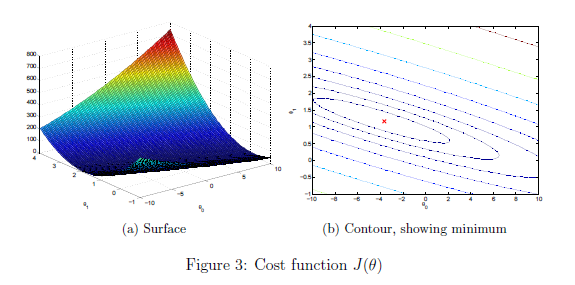

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

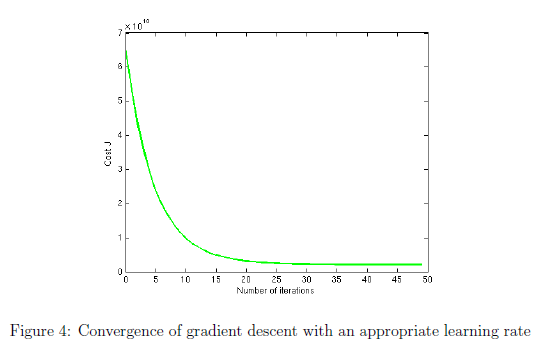

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

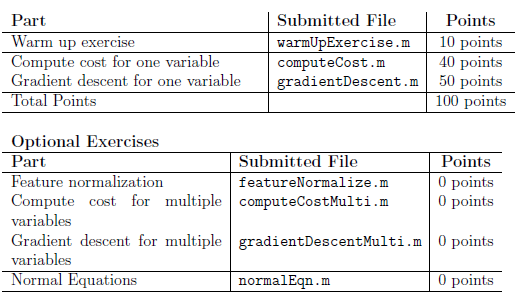

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.